clear all
close all

## part 1

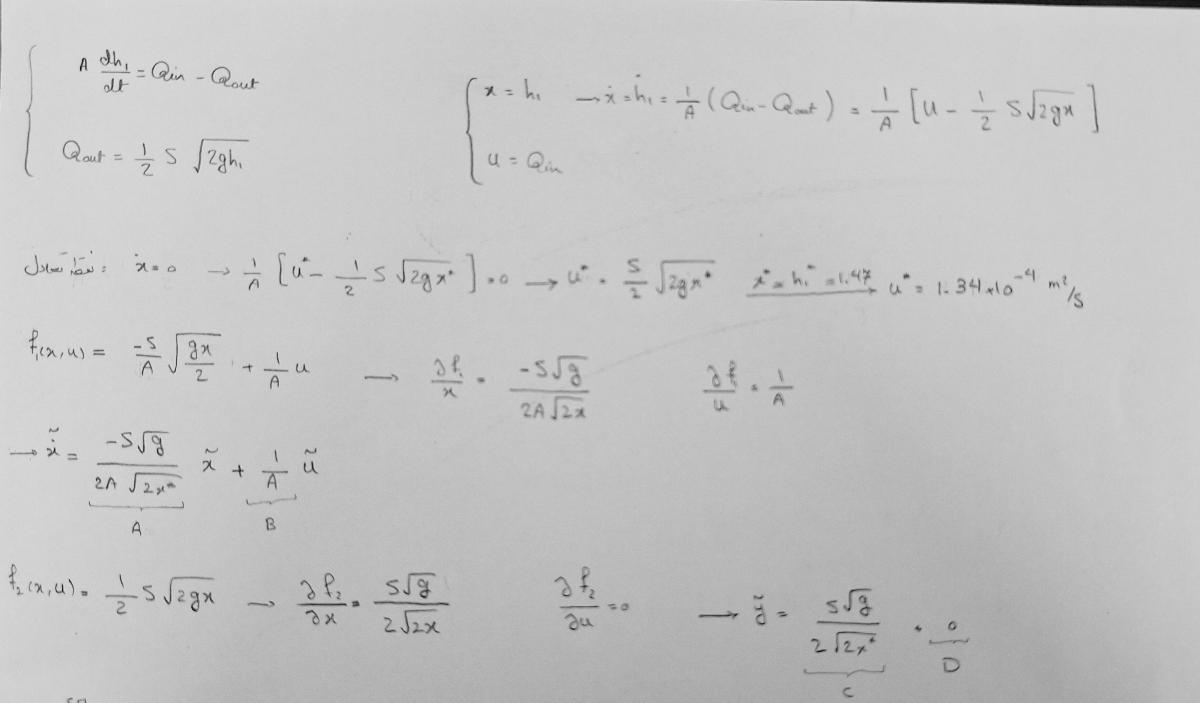

g = 9.81;
a = 15.4 *10^(-3);
S = 5 * 10^(-5);
XStar = 1.47;

A = (-1*sqrt(g/XStar)*S)/(2^(1.5)*a);
B = 1/a;
C = (sqrt(g/XStar)*S)/(2^(1.5));
D = 0;

[NUM, DEM] = ss2tf(A,B,C,D);
G = tf(NUM, DEM)

G =
 
    0.002965
  ------------
  s + 0.002965
 
Continuous-time transfer function.



همانطور که میبینیم چون قطب تابع تبدیل منفی است، این سیستم پایدار است

## part 2

feedbackG = feedback(G, 1)

feedbackG =
 
    0.002965
  ------------
  s + 0.005931
 
Continuous-time transfer function.



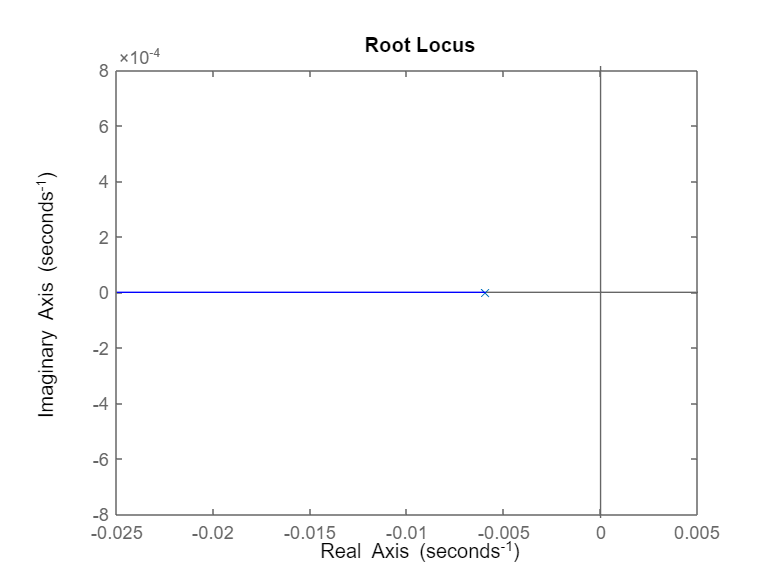


rlocus(feedbackG);

برای تمام بهره های مثبت پایدار است

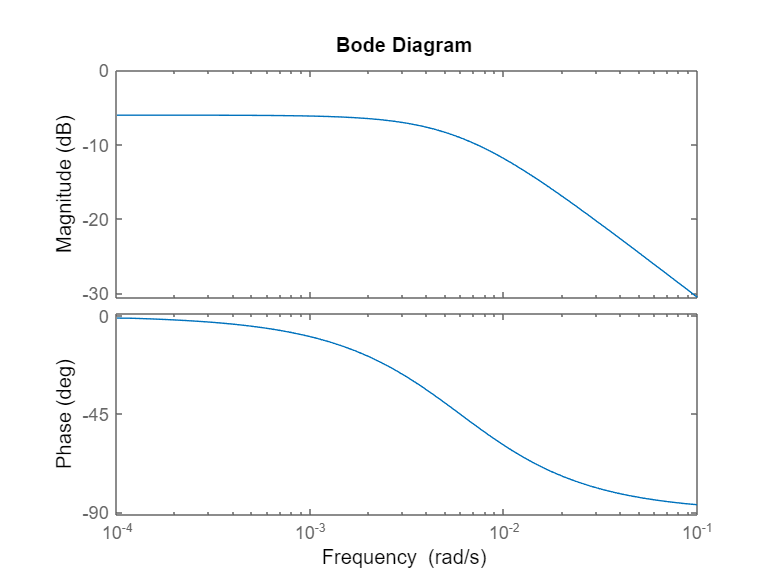

figure()
bode(feedbackG)

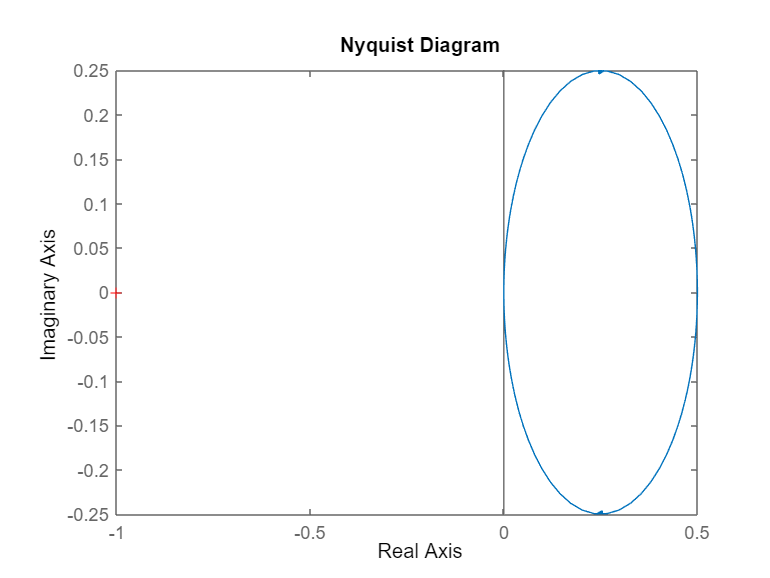


figure()
nyquist(feedbackG)


[Gm, Pm, Wgm, Wpm] = margin(feedbackG);
bandwidth = bandwidth(feedbackG);
fprintf('Phase Margin: %f degrees\n', Pm);

Phase Margin: Inf degrees


fprintf('Gain Margin: %f dB\n', 20*log10(Gm));

Gain Margin: Inf dB


fprintf('Bandwidth: %f rad/s\n\n', bandwidth);

Bandwidth: 0.005917 rad/s



همانطور که میبینیم چون نمودار اندازه صفر دسی بل را و نمودار فاز -180 را قطع نکرده اند، حاشیه فاز و حاشیه بهتره بینهایت هستند

## part 3 :

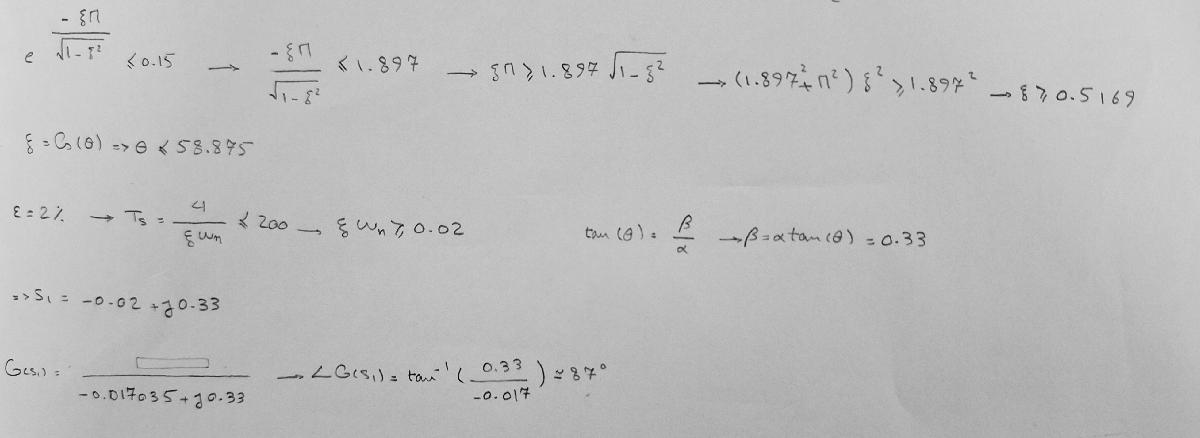

## gain controller

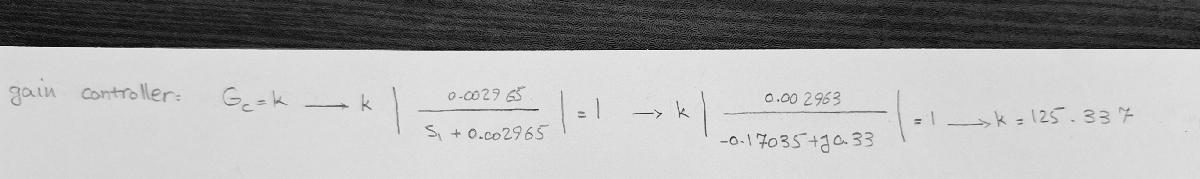

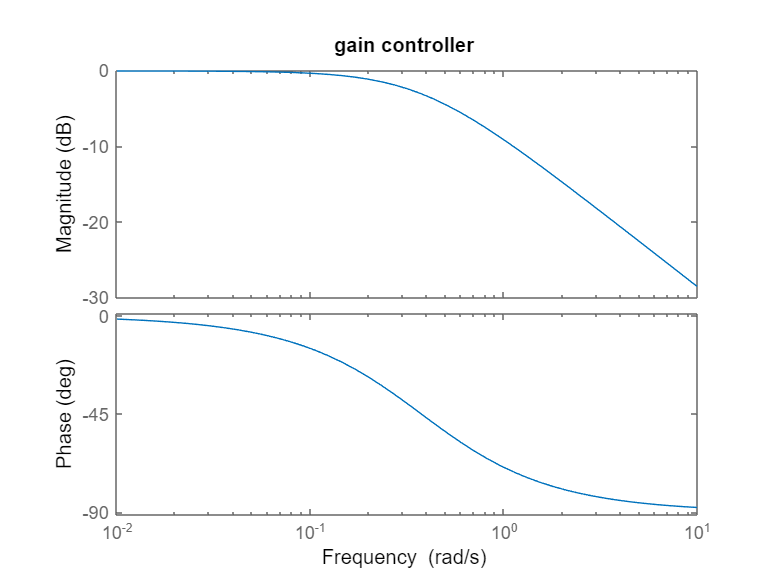

Kg = 125.337;
Gc1 = Kg;
feedbackGc1 = feedback(series(Gc1,G), 1);

figure()
bode(feedbackGc1)
title("gain controller")

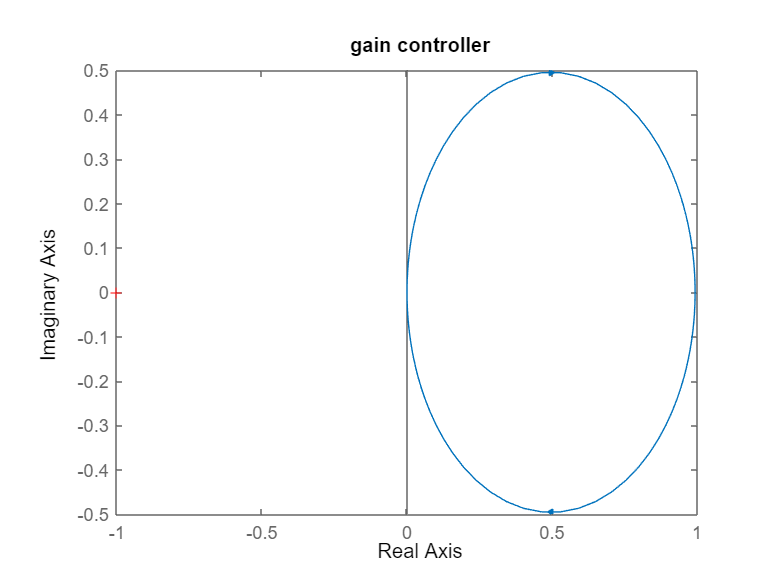

figure()
nyquist(feedbackGc1)
title("gain controller")

s = stepinfo(feedbackGc1)

s = struct with fields:
         RiseTime: 5.8644
    TransientTime: 10.4423
     SettlingTime: 10.4423
      SettlingMin: 0.8973
      SettlingMax: 0.9921
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9921
         PeakTime: 28.1495


## lead controller

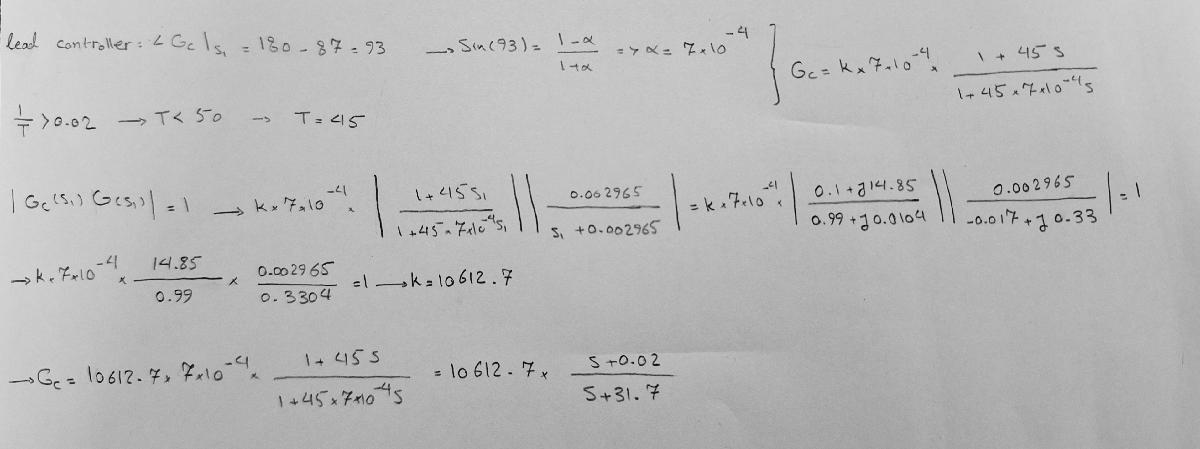

alpha = 7 * 10^(-4);
Klead = 10612.7;
T = 45;
s = tf('s');
Gc2 = Klead * alpha * (1+T*s)/(1+T*alpha*s)

Gc2 =
 
  334.3 s + 7.429
  ---------------
   0.0315 s + 1
 
Continuous-time transfer function.



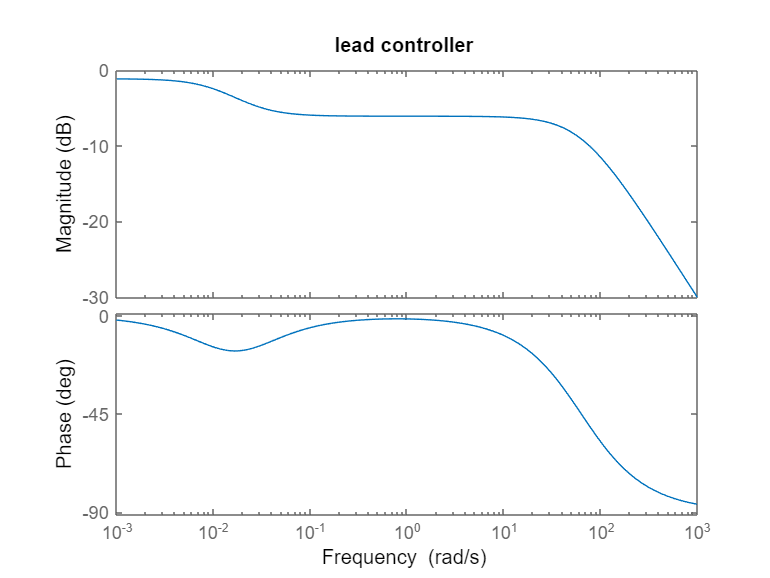

feedbackGc2 = feedback(series(Gc2,G), 1);

figure()
bode(feedbackGc2)
title("lead controller")

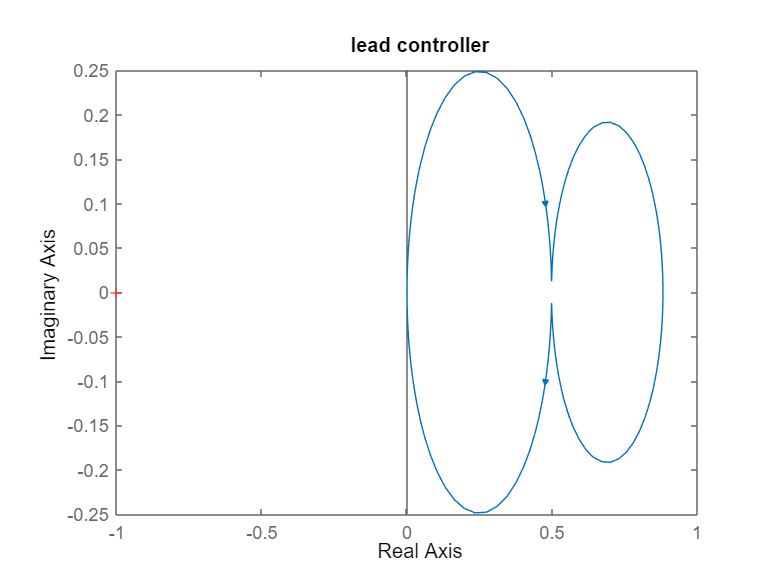

figure()
nyquist(feedbackGc2)
title("lead controller")

s = stepinfo(feedbackGc2)

s = struct with fields:
         RiseTime: 117.1366
    TransientTime: 245.3445
     SettlingTime: 245.3445
      SettlingMin: 0.7932
      SettlingMax: 0.8812
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8812
         PeakTime: 598.3679


## lag controller

از این کنترلر برای تغییر خطای حالت پایدار و اصلاح حاشیه های پایداری و برای وقتی که میخواهیم مکان ریشه تغییری نکند استفاده میکنیم و در اینجا قابل استفاده نیست

## PI controller

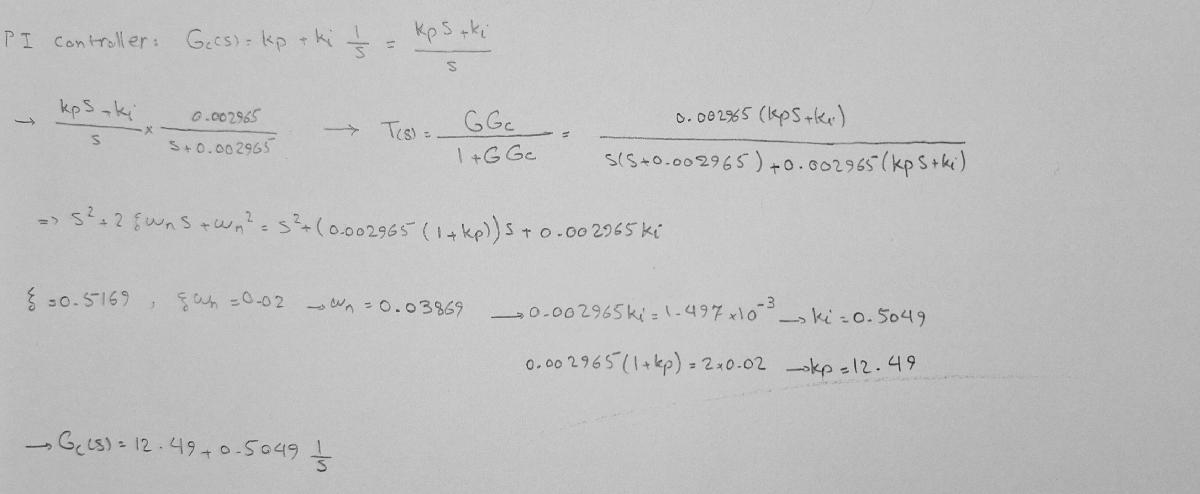

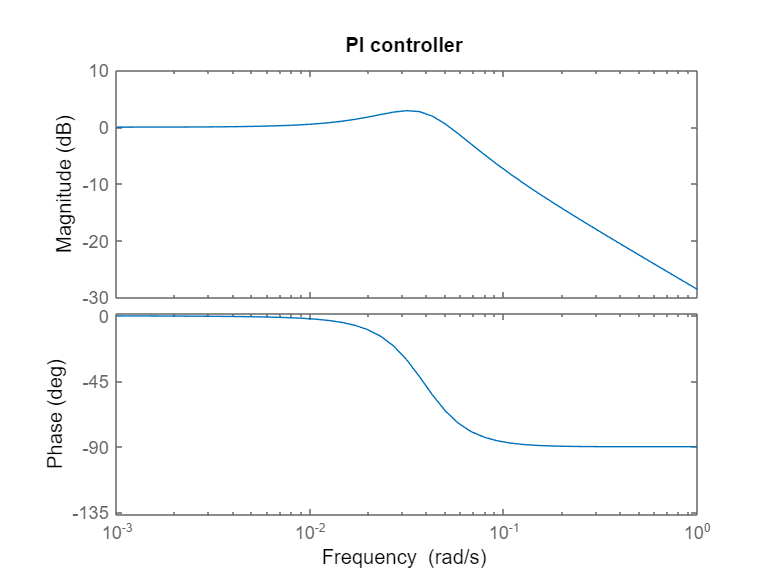

KpPI = 12.49;
KiPI = 0.5049;

s = tf('s');
Gc4 = KpPI + KiPI/s;
feedbackGc4 = feedback(series(Gc4,G), 1);

figure()
bode(feedbackGc4)
title("PI controller")

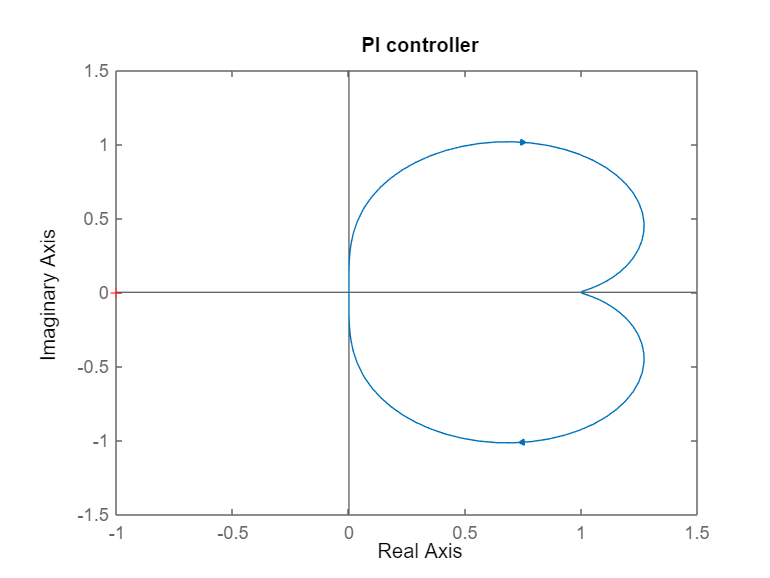

figure()
nyquist(feedbackGc4)
title("PI controller")

s = stepinfo(feedbackGc4)

s = struct with fields:
         RiseTime: 25.6443
    TransientTime: 192.7006
     SettlingTime: 192.7006
      SettlingMin: 0.9356
      SettlingMax: 1.2670
        Overshoot: 26.7043
       Undershoot: 0
             Peak: 1.2670
         PeakTime: 64.4676


## PID controller

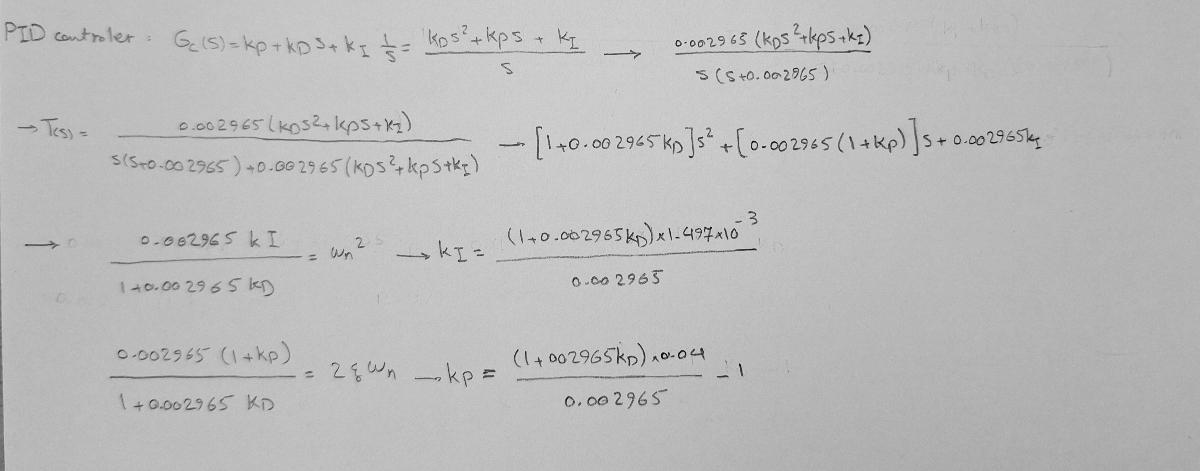

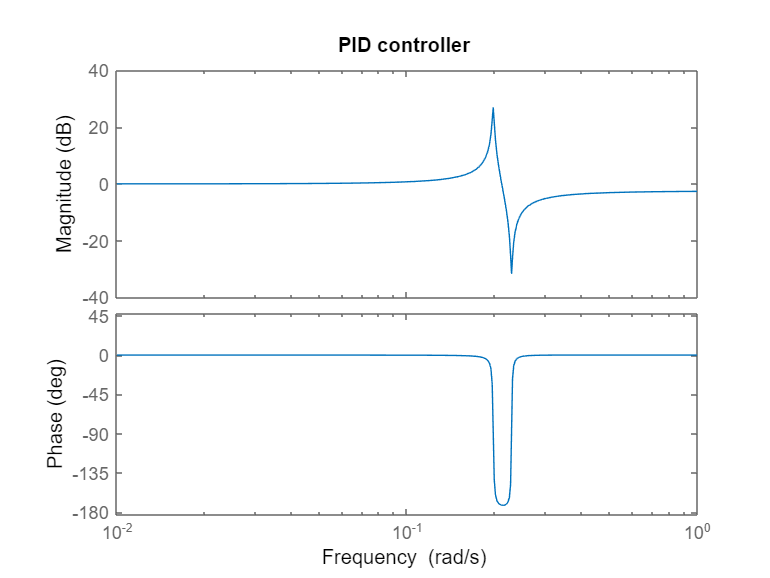

KdPID = 1000;
KpPID = (1+0.002965*KdPID)*1.497*10^(-3)/0.002965;
KiPID = (1+0.002965*KdPID)*0.04/0.002965 - 1;

s = tf('s');
Gc5 = KpPID + KdPID*s + KiPID/s;
feedbackGc5 = feedback(series(Gc5,G), 1);

figure()
bode(feedbackGc5)
title("PID controller")

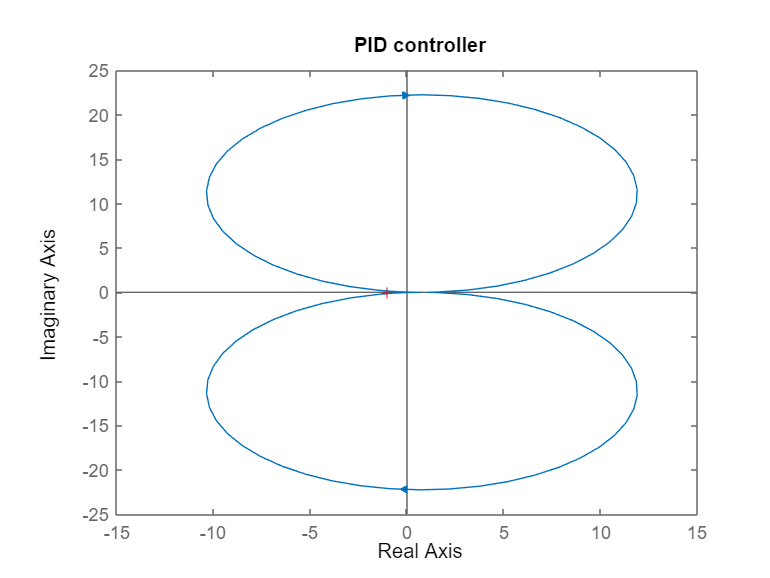

figure()
nyquist(feedbackGc5)
title("PID controller")

s = stepinfo(feedbackGc5)

s = struct with fields:
         RiseTime: 5.8787
    TransientTime: 3.4731e+03
     SettlingTime: 2.2519e+03
      SettlingMin: 0.7566
      SettlingMax: 1.2477
        Overshoot: 24.7734
       Undershoot: 0
             Peak: 1.2477
         PeakTime: 15.8566


## part 4

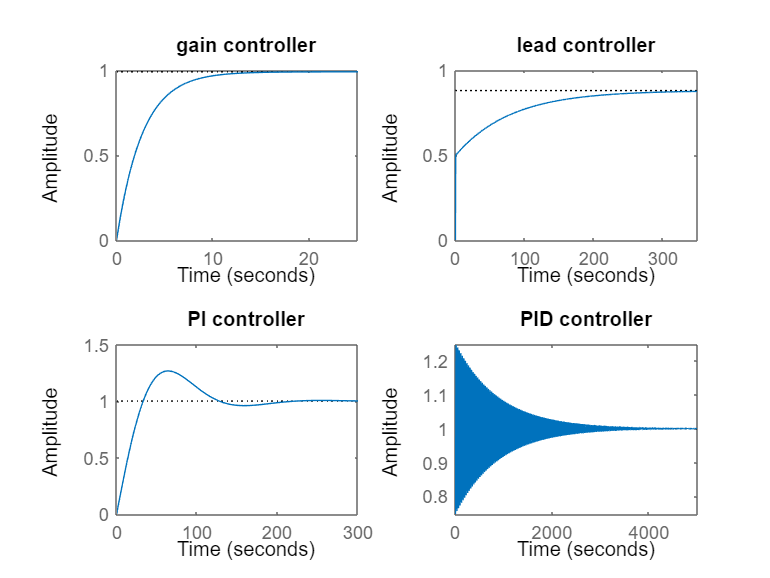

figure();

subplot(2,2,1);
step(feedbackGc1);
title("gain controller")

subplot(2,2,2);
step(feedbackGc2);
title("lead controller")

subplot(2,2,3);
step(feedbackGc4);
title("PI controller")

subplot(2,2,4);
step(feedbackGc5);
title("PID controller")

## part 5

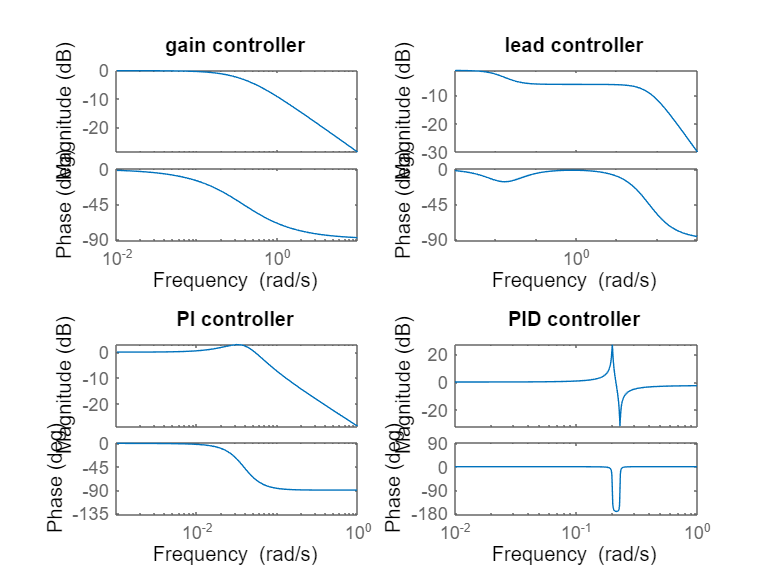

figure()
subplot(2,2,1);
bode(feedbackGc1)
title("gain controller")
subplot(2,2,2);
bode(feedbackGc2)
title("lead controller")
subplot(2,2,3);
bode(feedbackGc4)
title("PI controller")
subplot(2,2,4);
bode(feedbackGc5)
title("PID controller")

[Gm, Pm, Wgm, Wpm] = margin(feedbackGc1);
%bandwidth = bandwidth(feedbackGc1);
disp("gain controller:")

gain controller:


fprintf('Phase Margin: %f degrees\n', Pm);

Phase Margin: Inf degrees


fprintf('Gain Margin: %f dB\n\n', 20*log10(Gm));

Gain Margin: Inf dB



%fprintf('Bandwidth: %f rad/s\n\n', bandwidth);

[Gm, Pm, Wgm, Wpm] = margin(feedbackGc2);
%bandwidth = bandwidth(feedbackGc2);
disp("lead controller:")

lead controller:


fprintf('Phase Margin: %f degrees\n', Pm);

Phase Margin: Inf degrees


fprintf('Gain Margin: %f dB\n\n', 20*log10(Gm));

Gain Margin: Inf dB



%fprintf('Bandwidth: %f rad/s\n\n', bandwidth);

[Gm, Pm, Wgm, Wpm] = margin(feedbackGc4);
%bandwidth = bandwidth(feedbackGc4);
disp("PI controller:")

PI controller:


fprintf('Phase Margin: %f degrees\n', Pm);

Phase Margin: 111.360803 degrees


fprintf('Gain Margin: %f dB\n\n', 20*log10(Gm));

Gain Margin: Inf dB



%fprintf('Bandwidth: %f rad/s\n\n', bandwidth);

[Gm, Pm, Wgm, Wpm] = margin(feedbackGc5);
%bandwidth = bandwidth(feedbackGc5);
disp("PID controller:")

PID controller:


fprintf('Phase Margin: %f degrees\n', Pm);

Phase Margin: 8.010277 degrees


fprintf('Gain Margin: %f dB\n\n', 20*log10(Gm));

Gain Margin: Inf dB



%fprintf('Bandwidth: %f rad/s\n\n', bandwidth);

## part 6 : gain controller

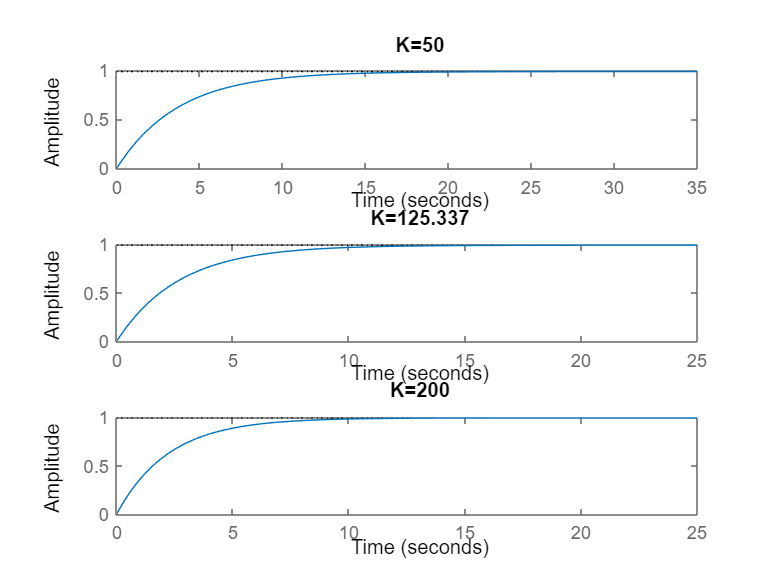

figure()
subplot(3,1,2)
step(feedbackGc1);
title("K=125.337")

Kg = 90;
Gc1 = Kg;
feedbackGc1 = feedback(series(Gc1,G), 1);

subplot(3,1,1)
step(feedbackGc1);
title("K=50")


Kg = 150;
Gc1 = Kg;
feedbackGc1 = feedback(series(Gc1,G), 1);

subplot(3,1,3)
step(feedbackGc1);
title("K=200")

## part 6 : lead controller

changing K:

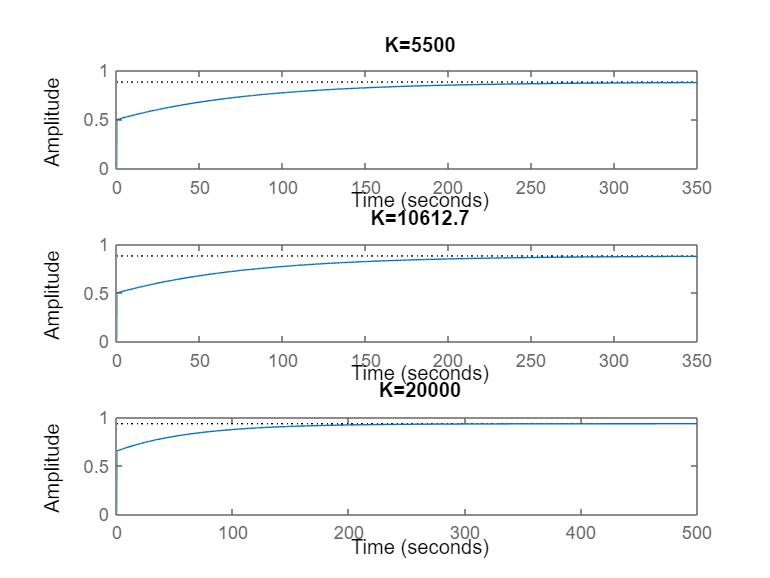

figure()
subplot(3,1,2)
step(feedbackGc2);
title("K=10612.7")

Klead = 10612.7;
s = tf('s');
Gc2 = Klead * alpha * (1+T*s)/(1+T*alpha*s);
feedbackGc2 = feedback(series(Gc2,G), 1);
subplot(3,1,1)
step(feedbackGc2);
title("K=5500")


Klead = 20000;
Gc2 = Klead * alpha * (1+T*s)/(1+T*alpha*s);
feedbackGc2 = feedback(series(Gc2,G), 1);

subplot(3,1,3)
step(feedbackGc2);
title("K=20000")

changing alpha:

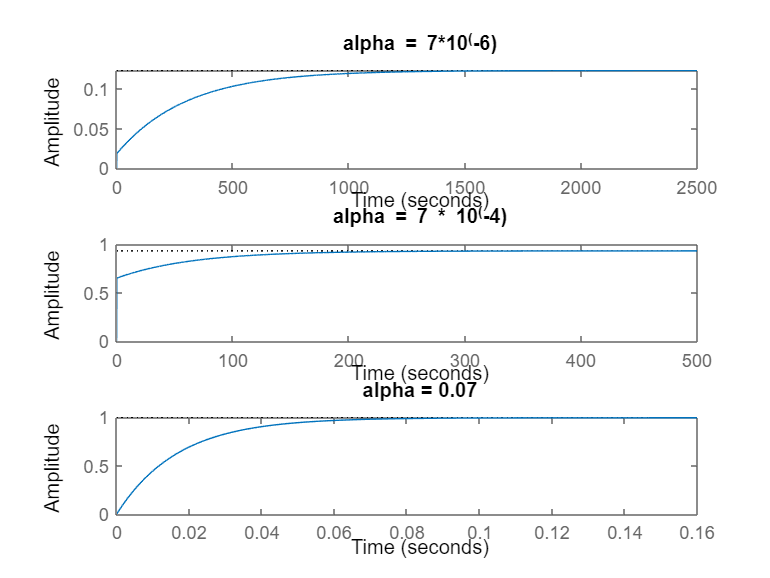

figure()
subplot(3,1,2)
step(feedbackGc2);
title("alpha = 7 * 10^(-4)")

alpha = 0.07;
Gc2 = Klead * alpha * (1+T*s)/(1+T*alpha*s);
feedbackGc2 = feedback(series(Gc2,G), 1);

subplot(3,1,3)
step(feedbackGc2);
title("alpha = 0.07")


alpha = 7*10^(-6);
Gc2 = Klead * alpha * (1+T*s)/(1+T*alpha*s);
feedbackGc2 = feedback(series(Gc2,G), 1);

subplot(3,1,1)
step(feedbackGc2);
title("alpha = 7*10^(-6)")

changing T:

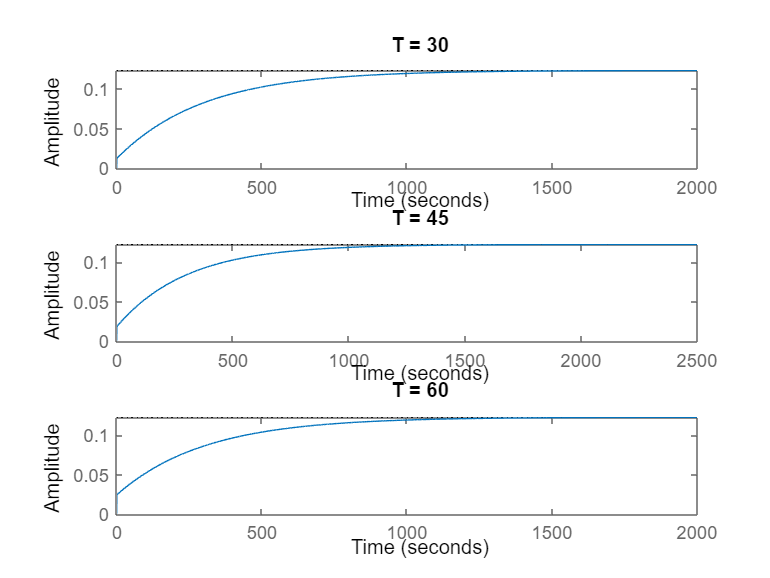

figure()
subplot(3,1,2)
step(feedbackGc2);
title("T = 45")

T = 30;
Gc2 = Klead * alpha * (1+T*s)/(1+T*alpha*s);
feedbackGc2 = feedback(series(Gc2,G), 1);

subplot(3,1,1)
step(feedbackGc2);
title("T = 30")


T = 60;
Gc2 = Klead * alpha * (1+T*s)/(1+T*alpha*s);
feedbackGc2 = feedback(series(Gc2,G), 1);

subplot(3,1,3)
step(feedbackGc2);
title("T = 60")